# ROZWIĄZAYWANIE UKŁADÓW RÓWNAŃ LINIOWYCH

## Metoda Jakobiego jako przykład metody iteracyjnej

Poniższy skrypt rozwiązuje układ równań metodą Jakobiego. Zwróć uwagę, że metoda Jakobiego zaimplementowana jest w postaci macierzowej zgodnie z logiką postaci kanonicznej metod iteracyjnych. 

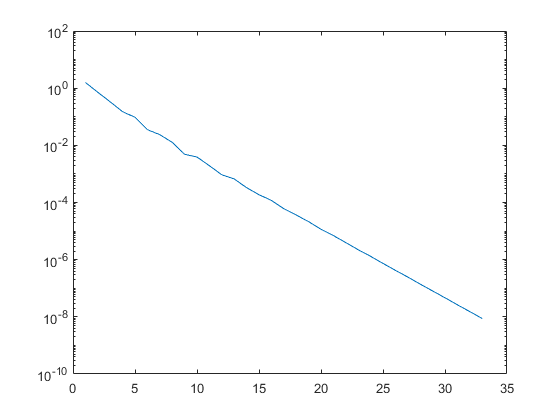

%Czyszczenie
clear all;close all;clc;

% Najpierw zdefiniujmy przykładowy układ równań:
A=[15 -2 3 0 6;...
   -3 19 1 -2 7.4;...
   2 -1 -17 1 6.7;...
   4 3 -5 17 9;...
   2 3.5 6.1 -4 -18.1];
b=[-1 2 3 0.5 13.1]';

% Dokonajmy teraz rozkładu macierzy A wg schematu metody Jakobiego
% uzyskując macierz M i wektor w
D=diag(diag(A));
L=tril(A)-D;
U=triu(A)-D;

M=-pinv(D)*(L+U);
w=pinv(D)*b;

%Przyjęcie parametrów dla algorytmu iteracyjengo 

%-> punkt startowy - losowy
x0=rand(numel(b),1);

%-> wymagana dokładność
delta0 = 1e-8;

%-> maksymalna ilość iteracji
i_max = 50;

%Implementacja metody Jakobiego
i=1;     %licznik iteracji 
error=5*delta0;
x_old=x0;
x=x_old; %wektor rozwiązań w kolejnych iteracjach;
n=i;     %wektor numerów iteracji do rysowania
err = [];%wektor błędów do rysowania
while( (error>=delta0) & (i<i_max))
    x_new = M*x(:,end)+w;
    error = norm(x_new-x_old);  %obliczenie estymaty błędu
    x_old=x_new;
    x=[x x_new]; 
    
    err=[err error];  
    n=[n i];i = i+1;
    
end

%Rysowanie błędu
semilogy(n, [err(1) err]);xlabel("# iteracji");ylabel("Estymata błędu")

W powyższej implementacji użyliśmy jawnego wzoru ogólnego zawierającego odwracanie macierzy:

Prawidłowa numerycznie implementacja stara się uniknąć odwracania macierzy i wychodzi z równania:

Które można potraktować jako układ równań liniowych i rozwiązać za pomocą operatora "\":

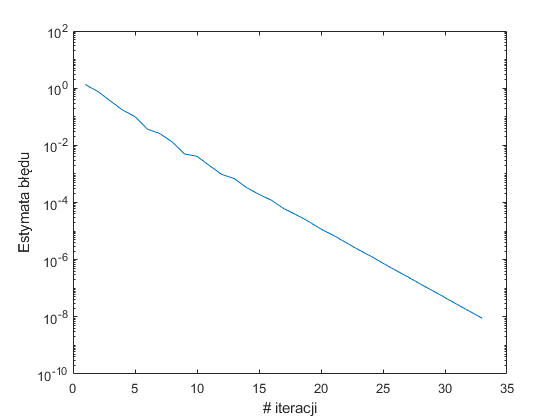

%Czyszczenie
clear all;close all;clc;

% Najpierw zdefiniujmy przykładowy układ równań:
A=[15 -2 3 0 6;...
   -3 19 1 -2 7.4;...
   2 -1 -17 1 6.7;...
   4 3 -5 17 9;...
   2 3.5 6.1 -4 -18.1];
b=[-1 2 3 0.5 13.1]';

% Dokonajmy teraz rozkłądu macierzy A wg schematu metody Jakobiego
% uzyskując macierz M i wektor w
D=diag(diag(A));
L=tril(A)-D;
U=triu(A)-D;

%Przyjęcie parametrów dla algorytmu iteracyjengo 

%-> punkt startowy - losowy
x0=rand(numel(b),1);

%-> wymagana dokłaność
delta0 = 1e-8;

%-> maksymalna ilość iteracji
i_max = 50;

%Implementacja metody Jakobiego
i=1;     %licznik iteracji 
error=5*delta0;
x_old=x0;
x=x_old; %wektor rozwiązań w kolejnych iteracjach;
n=i;     %wektor numerów iteracji do rysowania
err = [];%wektor błędów do rysowania
while( (error>=delta0) & (i<i_max))
    x_new = D \ (b - ((L+U)*x_old)); %ROZWIĄZANIE UKŁADU RÓWNAŃ LINIOWYCH
    error = norm(x_new-x_old);  %obliczenie estymaty błędu
    x_old=x_new;
    x=[x x_new]; 
    
    err=[err error];  
    n=[n i];i = i+1;
    
end

%Rysowanie błędu
semilogy(n, [err(1) err]);xlabel("# iteracji");ylabel("Estymata błędu")